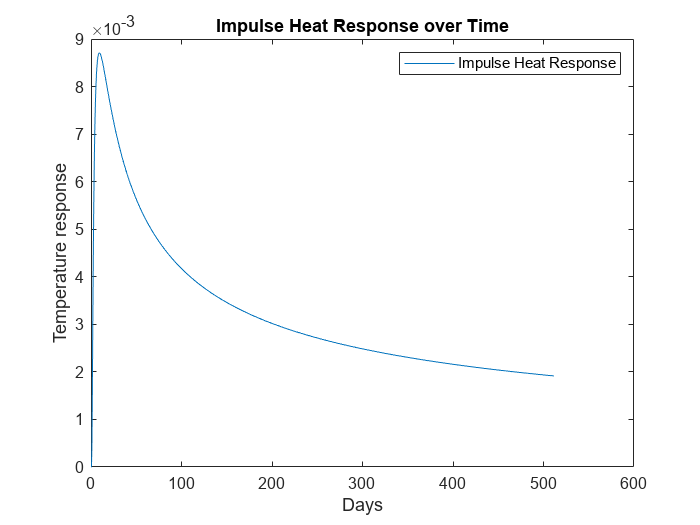

clc; 
clear all;

% Load temperature data
load('DATA.mat')

% Plot temperature response
figure;
plot(interval_jour_observations, h_reponse_impulsionnelle)
title('Impulse Heat Response over Time')
xlabel('Days')
ylabel('Temperature response')
legend('Impulse Heat Response')

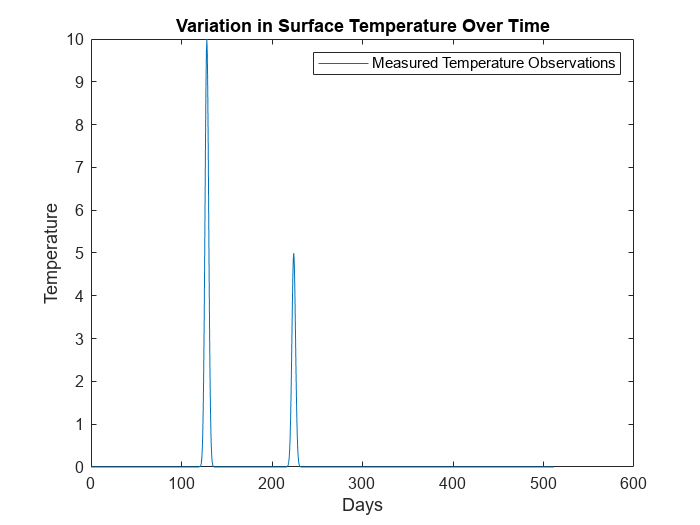


% Plot temperature observations
figure;
plot(interval_jour_observations, x)
title('Variation in Surface Temperature Over Time')
xlabel('Days')
ylabel('Temperature')
legend('Measured Temperature Observations')

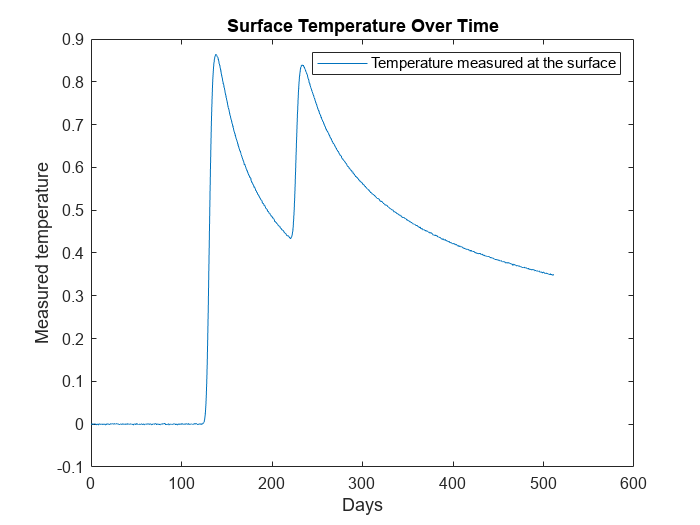


% Trace the temperature measured at the surface
plot(interval_jour_observations,y_tilda)
title('Surface Temperature Over Time')
xlabel('Days')
ylabel('Measured temperature')
legend('Temperature measured at the surface')

% Calculate the Gram matrix and its conditional number
Gram = transpose(H) * H;
condition_number = cond(Gram)

condition_number = Inf

% Enter an adjustment
eps=10e-6

eps = 1.0000e-05

I=eye(size(Gram))

I =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0   

Gram_inv=inv(Gram+eps*I)  ; 
% Estimate parameters using regularized linear regression
x_chap=Gram_inv*transpose(H)*y_tilda

x_chap =     0.0112
    0.0037
    0.0544
    0.0634
    0.0029
   -0.0776
   -0.1215
   -0.0978
    0.0082
    0.0843


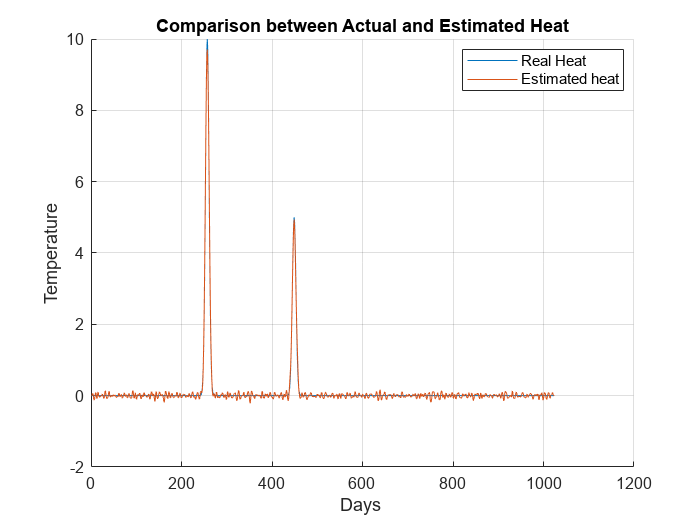

% View comparison between actual and estimated heat
figure;
hold on
plot(x, 'DisplayName', 'Real Heat')           % Trace actual heat
plot(x_chap, 'DisplayName', 'Estimated heat') % Trace the estimated heat
hold off
title('Comparison between Actual and Estimated Heat') 
xlabel('Days ') 
ylabel('Temperature') 
legend('Location', 'Best') 
grid; 

% Calculate mean square error
error_quad_moy = mean((x_chap - x).^2);

% Afficher l'erreur quadratique moyenne
disp(['L''erreur quadratique moyenne est : ', num2str(error_quad_moy)]);

L'erreur quadratique moyenne est : 0.0041143


% Calculate the correlation between original and estimated heats
corr_x = corr(x, x_chap);
% Show correlation
disp(['The correlation between original and estimated heats is : ', num2str(corr_x)]);

The correlation between original and estimated heats is : 0.99757


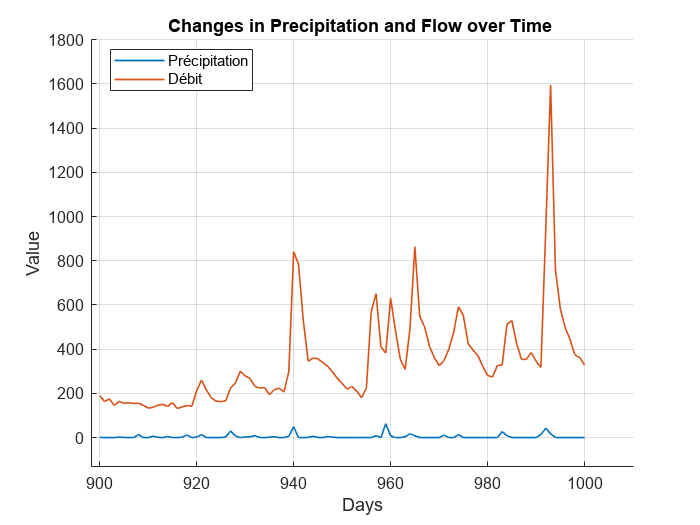


load("precip_discharge_data.txt")
time = precip_discharge_data(:, 1);
discharge = precip_discharge_data(:, 2) / 35.3146;
precip = precip_discharge_data(:, 3) * 25.4;

period = 900:1000;

% View rainfall (mm per day) and river flow (m³/s)
figure;
hold on 
plot(time(period), precip(period), 'LineWidth', 1, 'DisplayName', 'Précipitation')
plot(time(period), discharge(period), 'LineWidth', 1, 'DisplayName', 'Débit')
hold off
title('Changes in Precipitation and Flow over Time ')
xlabel('Days')
ylabel('Value')
legend('Location', 'Best') 
grid;

xlim([898.2 1010.2])
ylim([-133 1803])

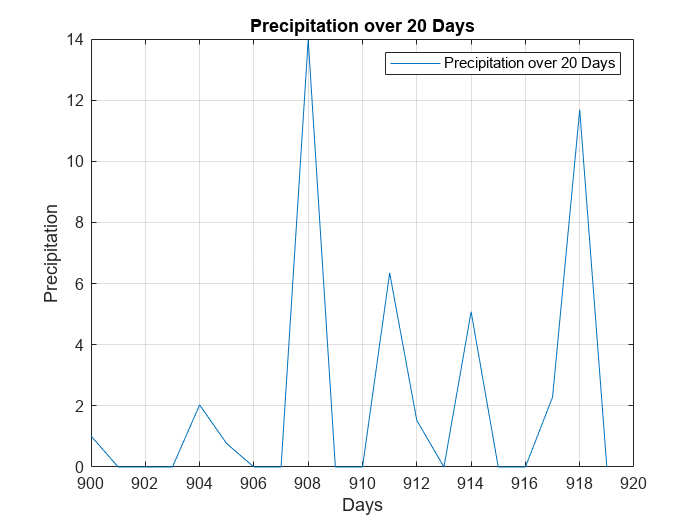

% Select a shorter time period
pp = 900:919;

% Plot precipitation for the shorter period
figure;
plot(time(pp), precip(pp))
title('Precipitation over 20 Days')
xlabel('Days')
ylabel('Precipitation')
legend('Precipitation over 20 Days')
grid; 

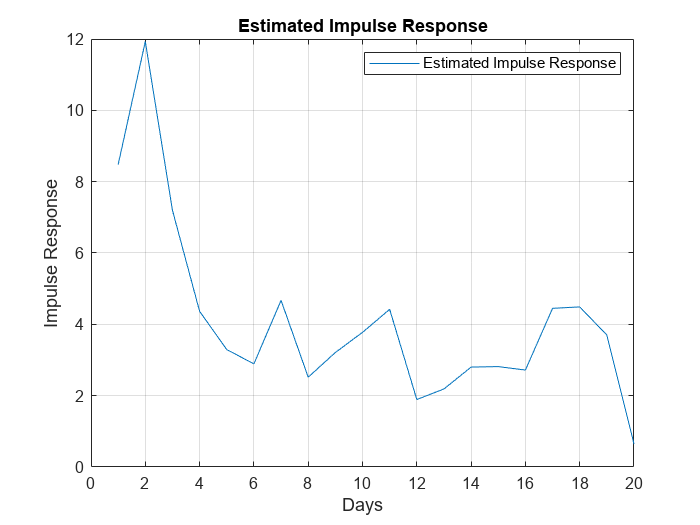

% Create a toeplitz matrix from precipitation data
X = tril(toeplitz(precip(900:1000)));
X = X(1:101, 1:20);

% Calculate the Gram matrix and its conditional number
Gram = transpose(X) * X;
condition_number = cond(Gram);

% Enter an adjustment
eps = 10e-6;
I = eye(size(Gram));
Gram_inv = inv(Gram + eps * I);

% Estimate impulse response using regularized linear regression
h_est = Gram_inv * transpose(X) * discharge(900:1000);

% View estimated impulse response
figure;
plot(h_est)
title('Estimated Impulse Response')
xlabel('Days')
ylabel('Impulse Response')
legend('Estimated Impulse Response')
grid  ;

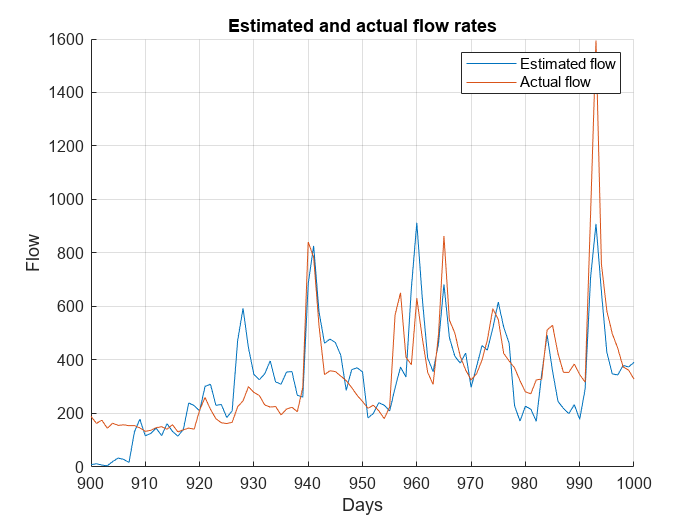

% Generate estimated flow using estimated impulse response
y_est = X * h_est;

% View estimated and original flow rates
figure;
hold on
plot(time(period), y_est)
plot(time(period), discharge(period))
hold off
title(' Estimated and actual flow rates ')
xlabel('Days')
ylabel('Flow')
legend('Estimated flow', 'Actual flow')
grid ; 

% Calculate the correlation between estimated and actual flow rates
corr_debit = corr(y_est, discharge(period));

% Calculate the root-mean-square error between Estimated Flow and Actual Flow
eqm_debit = mean((y_est - discharge(period)).^2);

% Show correlation
disp(['The correlation between Estimated Flow and Actual Flow is: ', num2str(corr_debit)]);

The correlation between Estimated Flow and Actual Flow is: 0.78071
